# Lazo cerrado (Control de Trayectoria)

Ana Itzel Hernández García 

Limpieza de pantalla

clear all
close all
clc

**Tiempo**

tf=33;             % Tiempo de simulación en segundos (s)
ts=0.02;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras 

**Condiciones iniciales **

Damos valores a nuestro punto inicial de posición y orientación

x1(1)=22.3;  %Posición inicial eje x
y1(1)=3.6;  %Posición inicial eje y
phi(1)=deg2rad(180); %Orientación inicial del robot 

Igualamos el punto de control con las proyecciones X1 y Y1 por su coincidencia

hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

**Trayectoria deseada** 

Puntos deseados

x_vec = [22.3, 18.3, 14.5, 11, 5.4,  3.4,  0, -3.5, -3.5,  -11.2,  -11.2, -18.3, -18.4,-14.6,-3.6, 0, 0, 0, 3.6];
y_vec = [3.6, 3.6, 7.7, 11, 25.8, 22.3, 22.3, 26, 21, 18.41, 14.6, 14.6, 10, 3.5, 3.7, 0, -3.7, -11, -18.4];

% Número de puntos en la trayectoria
N = length(t);

% Índice de tiempo normalizado de 0 a 1
t_puntos = linspace(0, 1, length(x_vec));
t_interp = linspace(0, 1, N);

% Interpolación lineal
hxd = interp1(t_puntos, x_vec, t_interp);
hyd = interp1(t_puntos, y_vec, t_interp);

Velocidades de la trayectoria deseada

hxdp=gradient(hxd, ts);
hydp=gradient(hyd, ts);

**Control, Bucle de simulación**

for k=1:N 

    %a)Errores de control (Aqui la posición deseada ya no es constante,
    % varia con el tiempo)
    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

    %b)Matriz Jacobiana
    J=[cos(phi(k)) -sin(phi(k));... %Matriz de rotación en 2D
       sin(phi(k)) cos(phi(k))];

    %c)Matriz de Ganancias
    K=[2 0;...
       0 2];
    
    %d)Velocidades deseadas
    hdp=[hxdp(k);hydp(k)];

    %e)Ley de Control:Agregamos las velocidades deseadas
    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 

**Aplicación de control al robot**

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)

MODELO CINEMATICO

    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end


**Simulación virtual 3D**

Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

% Calcular rangos automáticamente basados en la trayectoria real
minX = min(x1) - 1;
maxX = max(x1) + 1;
minY = min(y1) - 1;
maxY = max(y1) + 1;

view(2); % Vista 2D
axis([minX maxX minY maxY 0 1]); % Rango ajustado a la trayectoria real

Límites automáticos

xmin_lim = min(x_vec) - 2;
xmax_lim = max(x_vec) + 2;
ymin_lim = min(y_vec) - 2;
ymax_lim = max(y_vec) + 2;
axis([xmin_lim xmax_lim ymin_lim ymax_lim 0 1]);


Graficar robots en la posicion inicial

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

Graficar Trayectorias

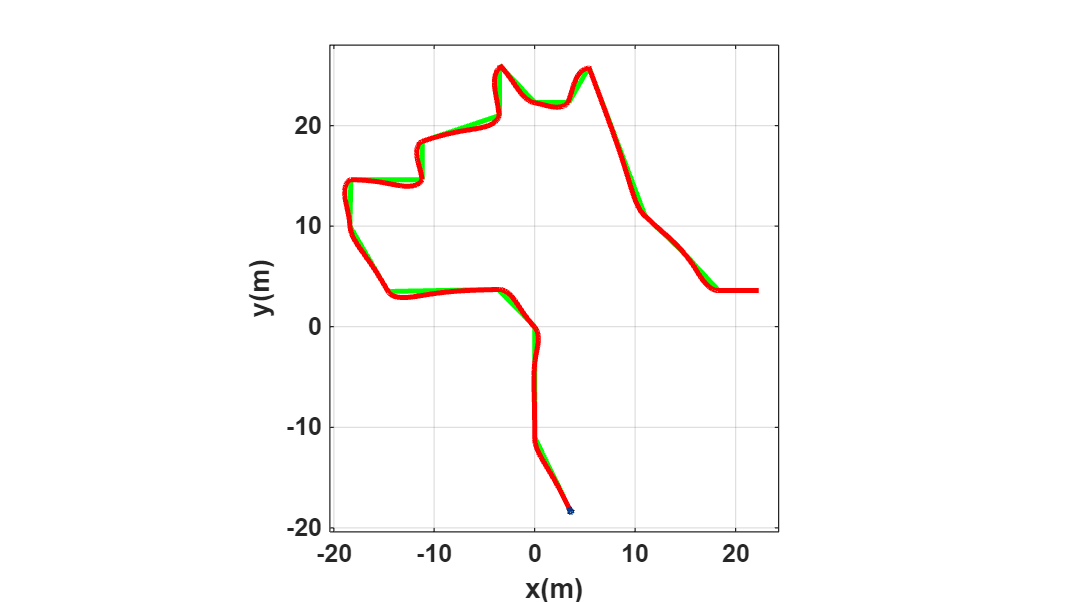

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'g','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial
% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

**Graficas**

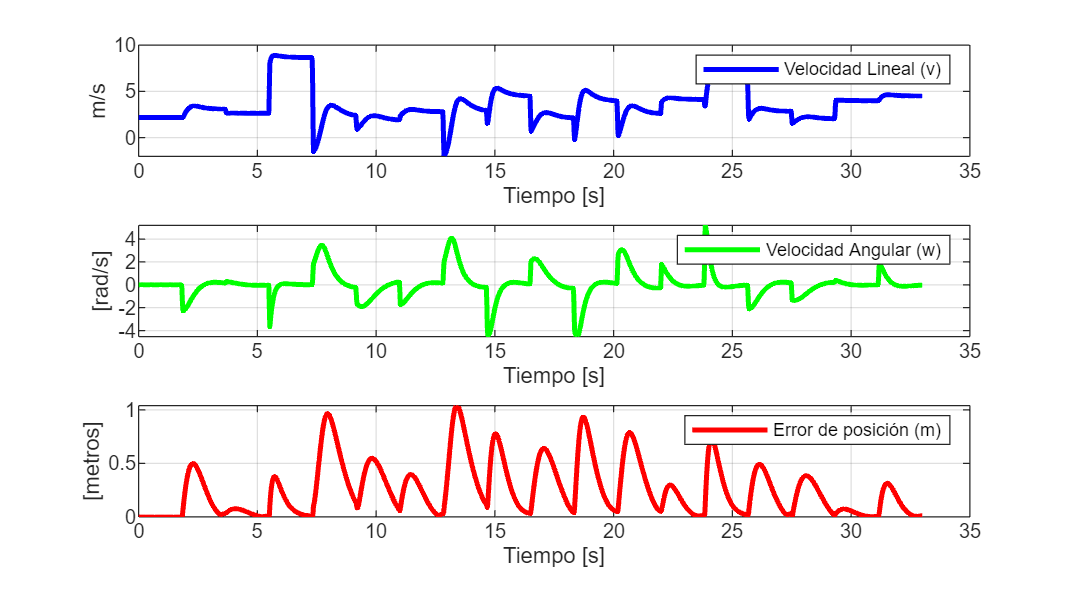

graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(311)
plot(t,v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t,w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t,Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');